## MT3005 - Clase 5

Emplearemos la Robotics Toolbox para obtener los modelos cinemáticos de los robots de nuestros ejemplos. Primero, iniciaremos con la cinemática directa del manipulador SCARA:

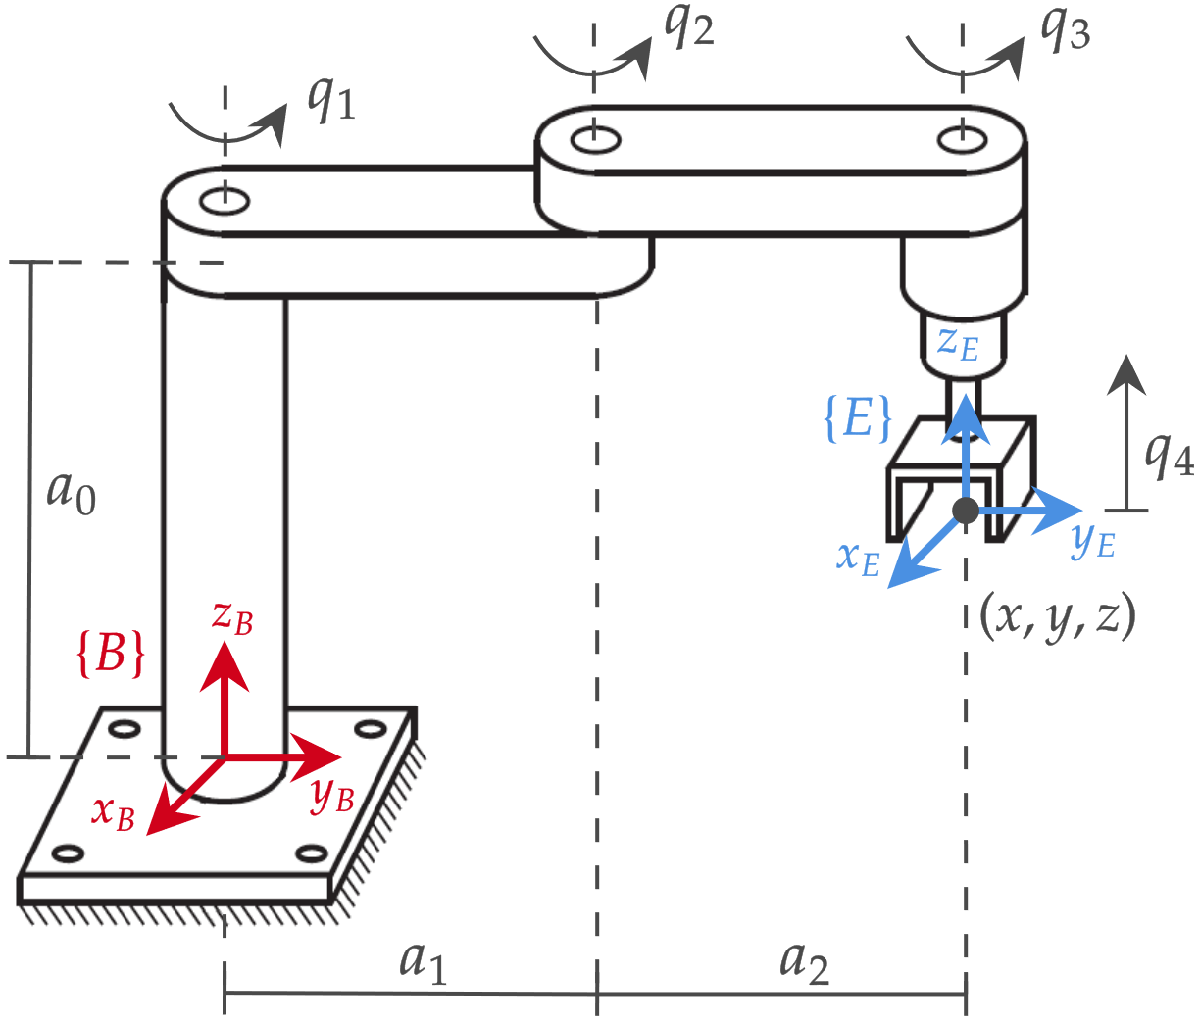

Para este caso, tendremos dos maneras de emplear la Toolbox para obtener "a mano" la cinemática directa:

% Definimos la configuración del robot mediante variables simbólicas
syms q1 q2 q3 q4

% Parámetros/dimensiones (fijos) del robot
a0 = 1;
a1 = 0.5;
a2 = 0.5;

% FORMA 1: composición de transformaciones elementales
BT_E1(q1,q2,q3,q4) = transl(0,0,a0)*trotz(q1)*transl(0,a1,0)*trotz(q2)*...

$$BT\_E1(q1, q2, q3, q4) = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & -\frac{\sin\left(q_{1}\right)}{2}-\frac{\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)}{2}-\frac{\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{2}\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & \frac{\cos\left(q_{1}\right)}{2}+\frac{\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{2}-\frac{\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{2}\\ 0 & 0 & 1 & 1-q_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)-\sin\left(q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)\\ \sigma_{2}=\sin\left(q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ \sigma_{3}=\cos\left(q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right) \end{array}$$

transl(0,a2,0)*trotz(q3)*transl(0,0,-q4)

% FORMA 2: mediante la función auxiliar trchain
BT_E2 = trchain('Tz(a0)*Rz(q1)*Ty(a1)*Rz(q2)*Ty(a2)*Rz(q3)*Tz(-q4)', ...
    [q1,q2,q3,q4])

$$BT\_E2 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & -\frac{\sin\left(q_{1}\right)}{2}-\frac{\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)}{2}-\frac{\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{2}\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & \frac{\cos\left(q_{1}\right)}{2}+\frac{\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{2}-\frac{\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{2}\\ 0 & 0 & 1 & 1-q_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)-\sin\left(q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)\\ \sigma_{2}=\sin\left(q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ \sigma_{3}=\cos\left(q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right) \end{array}$$


% Posición del efector final del manipulador
p = BT_E2(1:3,4)

$$p = \left(\begin{array}{c} -\frac{\sin\left(q_{1}\right)}{2}-\frac{\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)}{2}-\frac{\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{2}\\ \frac{\cos\left(q_{1}\right)}{2}+\frac{\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{2}-\frac{\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{2}\\ 1-q_{4} \end{array}\right)$$

Bajo la convención de Denavit-Hartenberg, la Toolbox nos simplifica las cosas y nos permite definir las juntas y luego combinarlas para formar el manipulador serial planar del segundo ejemplo:

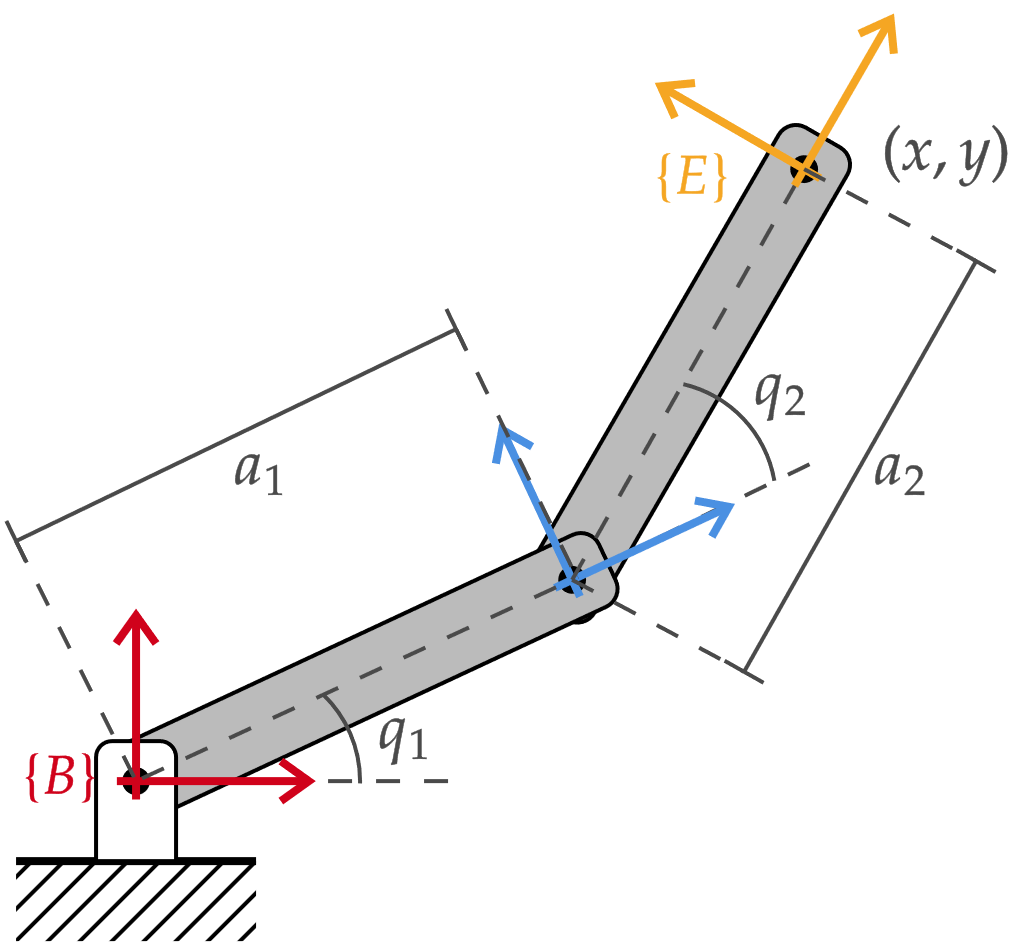

Cada junta definida corresponde a una fila de la tabla de parámetros DH.

% Cada junta puede ser o revoluta y prismática y debemos definir los parámetros 'theta', 
% 'd', 'a' y 'alpha' que se necesiten (caso contrario se establecen en cero).
% NOTA: las revolutas no permiten definir 'theta' y las prismáticas 'd'.
J1 = Revolute('a', 1);
J2 = Revolute('a', 1);

% Definimos el robot como un objeto de tipo SerialLink, el primer argumento es un vector de 
% objetos de tipo Link (que en este caso son las dos juntas revoluta) seguido del nombre 
% a asignarle al robot.
robotRR = SerialLink([J1, J2], 'name', 'robotRR')

 
robotRR = 
 
robotRR:: 2 axis, RR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



% Puede emplearse la función fkine para obtener la cinemática directa del manipulador 
% para una configuración específica:
robotRR.fkine([30, 40], 'deg')

 

ans = 
   -0.4453   -0.8954         0    -1.358
    0.8954   -0.4453         0    0.4856
         0         0         1         0
         0         0         0         1


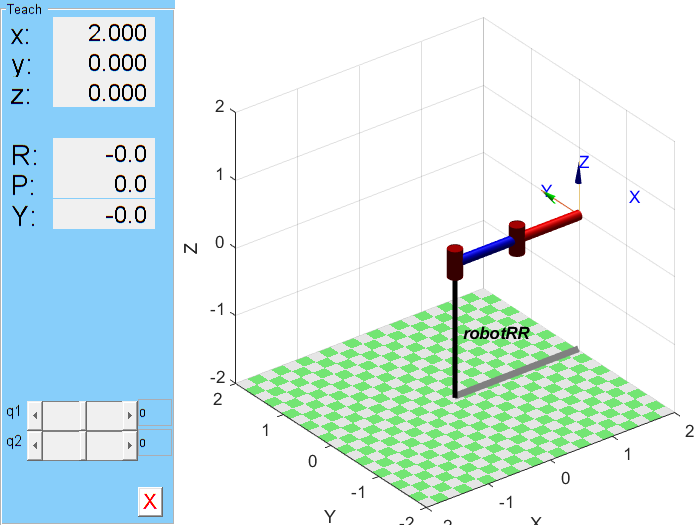


% Puede usarse la función plot para visualizar el robot en una configuración determinada 
% (en este caso especificada por el vector q0:
q0 = [0, 0];
robotRR.plot(q0);

% La función teach permite interactuar de forma gráfica con el robot, modificando con el 
% mouse cada uno de los parámetros de la configuración:
robotRR.teach();

Finalmente, podemos repetir el mismo procedimiento para el robot SCARA pero empleando los parámetros DH.

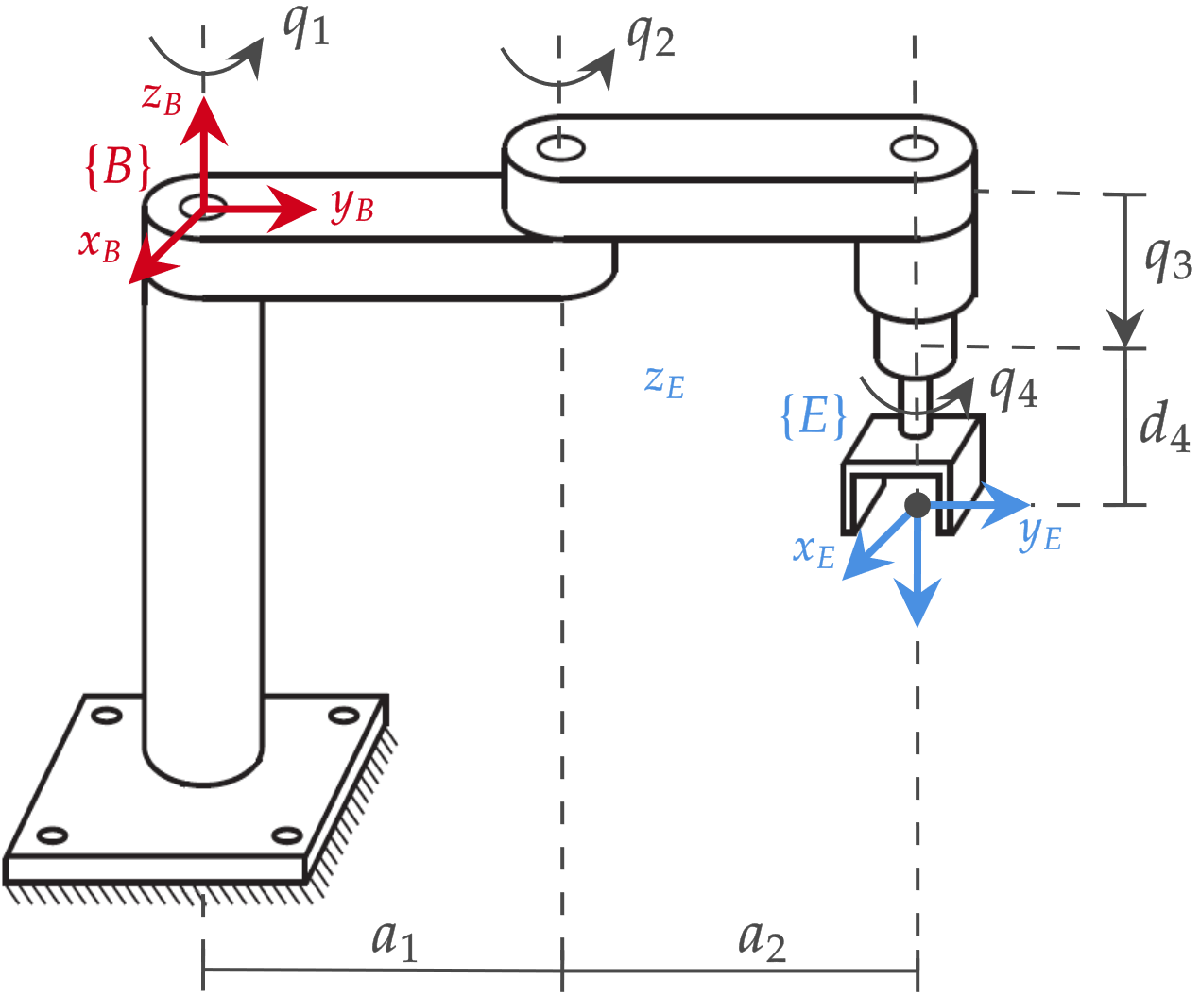

% Juntas del robot
J1 = Revolute('a', 0.5);
J2 = Revolute('a', 0.5, 'alpha', pi);
J3 = Prismatic();
J3.qlim = [0, 0.5]; % deben colocarse los límites para la prismática
J4 = Revolute('d', 0.1);

% Definimos el robot como un objeto SerialLink
scara = SerialLink([J1, J2, J3, J4], 'name', 'SCARA')

 
scara = 
 
SCARA:: 4 axis, RRPR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|        0.5|          0|          0|
|  2|         q2|          0|        0.5|    3.14159|          0|
|  3|          0|         q3|          0|          0|          0|
|  4|         q4|        0.1|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



% Generamos la cinemática directa para una configuración aleatoria
q1 = rand(1,4);
scara.fkine(q1)

 

ans = 
    0.9833    0.1820         0    0.7759
    0.1820   -0.9833         0    0.6289
         0         0        -1   -0.3785
         0         0         0         1


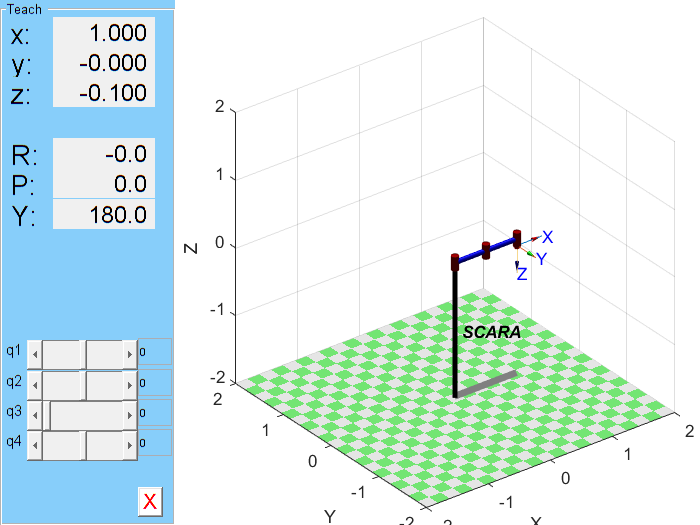


% Se visualiza el robot en una configuración específica
q0 = [0, 0, 0, 0];
scara.plot(q0, 'workspace', 2*[-1, 1, -1, 1, -1, 1], 'reach', 1);

% Interactuamos gráficamente con el modelo cinemático del robot
scara.teach();

La Toolbox incluye también varios modelos de manipuladores populares, por ejemplo:

% Robot Puma 560
mdl_puma560
q0 = zeros(1,6);

% Graficamos e interactuamos
p560.plot3d(q0);

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


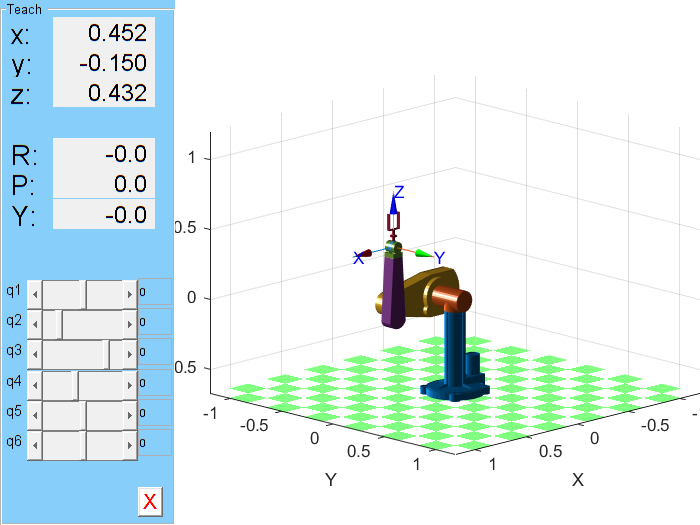

p560.teach('view', 'top');